# Final Project: CNN Portion

**Author:** Jack Bonney

**Student ID:** 4555214

**D Value:** 14

This live-script will walk through the processing involved with performing CNN on an image classification dataset. The dataset used is a collection of playing cards for all 53 types, the 13 base cards in each suit and the joker card. The data will be run through the google mobilenetv2 pretrained model. 

% Initialization
clc
clear
D = 14; % Personalization, will be used for RNG seeding
rng(D); % Set rng for reproducability

## Model Parameters

TrainingWeight = 0.9; % How much of the total data should be training: 0-1
K = 2; % How many validation splits should be done for the training data, minimum should be 5 realisticly
TotalTrials = 1; % How many total trials

## Sorting into Training and Testing Data

% LOADING THE DATA 
data = imageDatastore("dataset\","IncludeSubfolders",true,"LabelSource",'foldernames');
[values, cardTypes] = grp2idx(data.Labels); % Gets number values for each card type, and where they are in the datastore
% SORTING THE DATA INTO TRAINING AND TESTING
X_train = zeros(224,224,3,round(TrainingWeight*length(values)));
X_test = zeros(224,224,3,round((1-TrainingWeight)*length(values)));
y_train = zeros(round(TrainingWeight*length(values)),1);
y_test = zeros(round((1-TrainingWeight)*length(values)),1);
% Spliting into individual label
temp = imread(cell2mat(data.Files(1)));
%
trainpointer = 1;
testpointer = 1;
for val = 1:max(values) % Loops over every possible card type
    indicies = find(values==val); % Gets all of the indicies for a give value
    shuffle = indicies(randperm(length(indicies)));
    % Loop over each image, store it in 
    for trainImg = 1:round(length(indicies)*TrainingWeight)
        X_train(:,:,:,trainpointer+trainImg-1) = readimage(data,shuffle(trainImg));
    end
    for testImg = 1:round(length(indicies)*(1-TrainingWeight))
        X_test(:,:,:,testpointer+testImg-1) = readimage(data,shuffle(testImg+round(length(indicies)*TrainingWeight)));
    end
    % Getting numerical lables
    y_train(trainpointer:trainpointer+round(length(indicies)*TrainingWeight)-1) = values(shuffle(1:round(TrainingWeight*length(indicies))));
    y_test(testpointer:testpointer+round(length(indicies)*(1-TrainingWeight))-1) = values(shuffle(round(TrainingWeight*length(indicies))+1:length(indicies)));
    % Updating Pointers
    trainpointer = trainpointer + round(length(indicies)*TrainingWeight);
    testpointer = testpointer + round(length(indicies)*(1-TrainingWeight));
end

## Showing success of train/test split

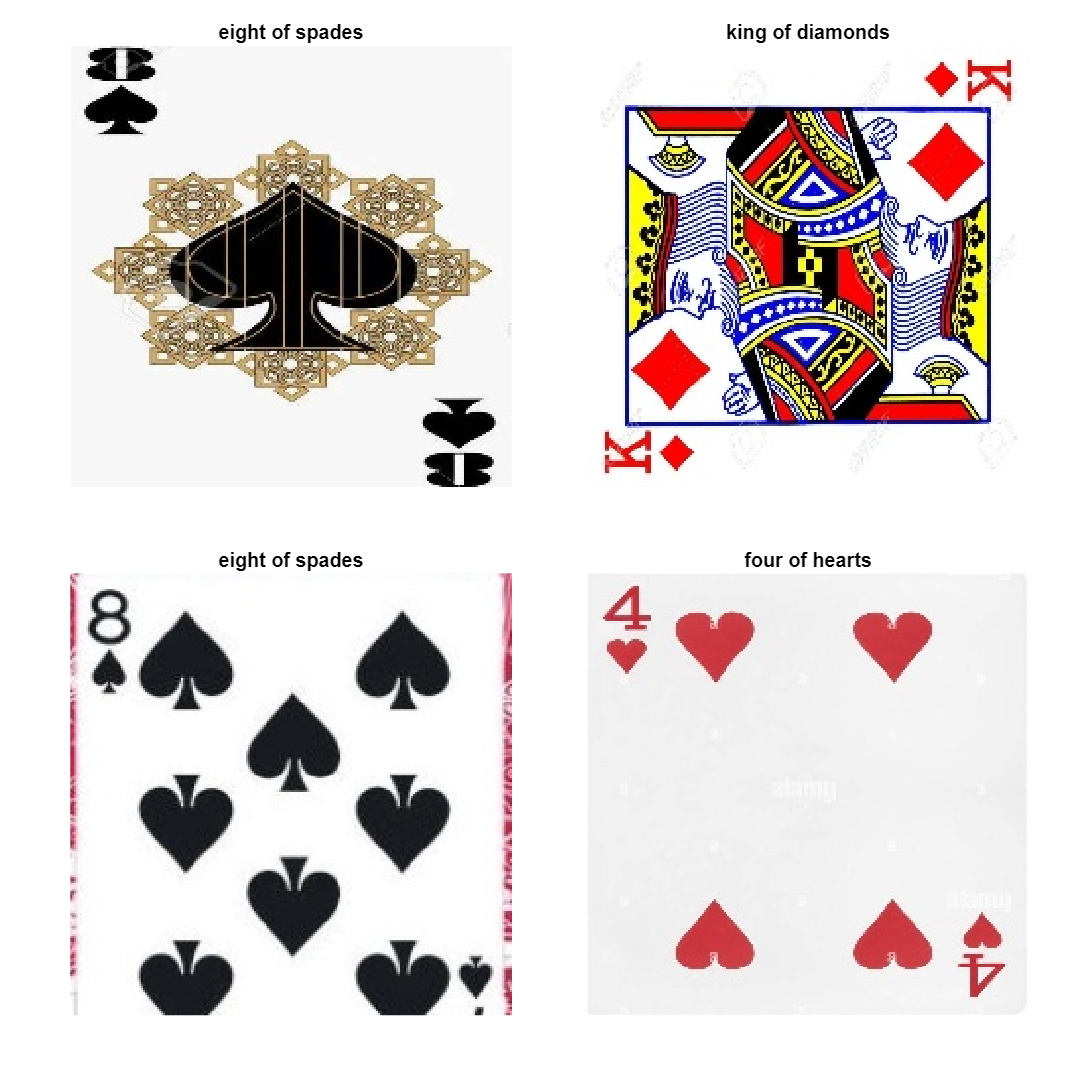

% Show traing images
testing = randperm(length(y_train),4);
datasetImagesTrain = figure('Position',[100,100,1000,1000]);
tiledlayout(2,2,'Padding','compact','TileSpacing','compact')
for idx = 1:4
    nexttile;
    imshow(uint8(X_train(:,:,:,testing(idx))))
    axis off;
    title(cardTypes(y_train(testing(idx))));
end
filename = sprintf('trainImages.png');
outputFile = fullfile("figures/",filename);
exportgraphics(datasetImagesTrain,outputFile,'Resolution',1200);

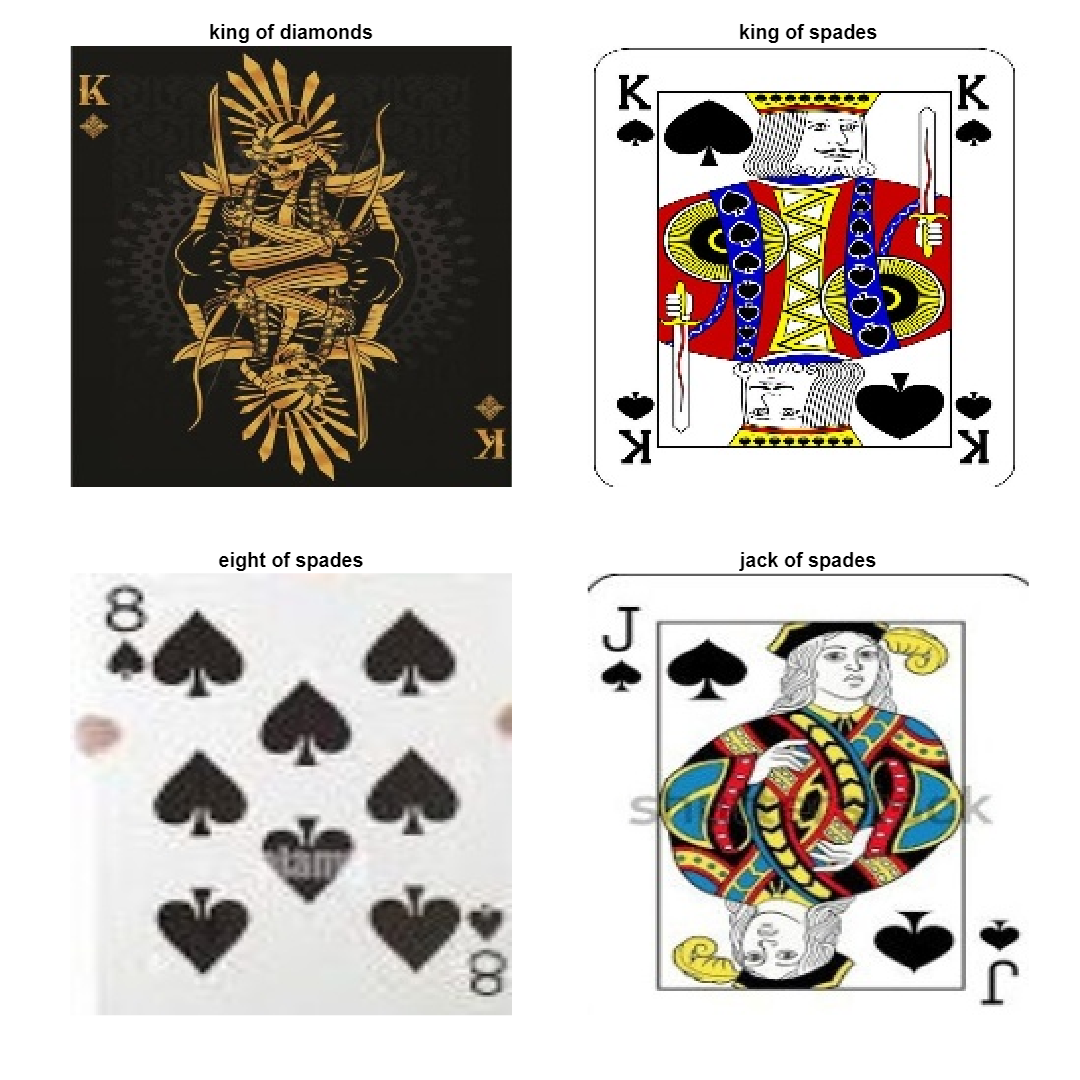

% Show traing images
testing = randperm(length(y_test),4);
datasetImageTest = figure('Position',[100,100,1000,1000]);
tiledlayout(2,2,'Padding','compact','TileSpacing','compact')
for idx = 1:4
    nexttile;
    imshow(uint8(X_test(:,:,:,testing(idx))))
    axis off;
    title(cardTypes(y_test(testing(idx))));
end
filename = sprintf('testImages.png');
outputFile = fullfile("figures/",filename);
exportgraphics(datasetImageTest,outputFile,'Resolution',1200);

## Getting the CNN working via Mobilenetv2

a

% Set up the network
net = mobilenetv2;
lgraph = layerGraph(net);
% Swap the final layers with what I have
newLayers = [
    fullyConnectedLayer(max(values),'Name','fc_new')
    softmaxLayer('Name','softmax')
    classificationLayer('Name','cardOutput')
];
%
lgraph = replaceLayer(lgraph,'Logits',newLayers(1));
lgraph = replaceLayer(lgraph,'Logits_softmax',newLayers(2));
lgraph = replaceLayer(lgraph,'ClassificationLayer_Logits',newLayers(3));
% Freeze Layers
layers = lgraph.Layers;
connections = lgraph.Connections;
for i = 1:numel(layers)
    % Get name of current layer
    layerName = layers(i).Name;
    if contains(layerName,"block_16") || contains(layerName,"Conv_1") || strcmp(layerName,"fc_new")
        continue;
    end
    if isprop(layers(i),'WeightLearnRateFactor')
        layers(i).WeightLearnRateFactor = 0;
    end
    if isprop(layers(i),'BiasLearnRateFactor')
        layers(i).BiasLearnRateFactor = 0;
    end
    % Update the layer
    lgraph = replaceLayer(lgraph,layerName,lgraph.Layers(i));
end

% Get the folds
crossFolds = cvpartition(y_train,"KFold",K);
accuarcies = zeros(K,1);
for fold = 1:K
    % Get the training and validation splits
    trainingIdx = training(crossFolds, fold);
    validationIdx = test(crossFolds, fold);
    % Get the sections from X and y train
    cv_X_train = X_train(:,:,:,trainingIdx);
    cv_y_train = categorical(y_train(trainingIdx));
    cv_X_val = X_train(:,:,:,validationIdx);
    cv_y_val = categorical(y_train(validationIdx));
    % Create Image stores (Its what the CNN algorithms want
    dataTrain = augmentedImageDatastore([224,224,3],cv_X_train,cv_y_train);
    dataValid = augmentedImageDatastore([224,224,3],cv_X_val,cv_y_val);
    % Setting up the options for the algorithim
    options = trainingOptions("adam",'MiniBatchSize',4,'MaxEpochs',5,'ValidationData',dataValid,'Verbose',false,'ExecutionEnvironment','gpu');
    % Run the model
    results = trainNetwork(dataTrain,lgraph,options);
    % Get the accuracy
    prediction = classify(results,dataValid);
    accuarcies(fold) = mean(prediction == cv_y_val);
    % Clear GPU
    reset(gpuDevice);
    clear results;
end

accuarcies =     0.7111
         0


accuarcies =     0.7111
    0.7241


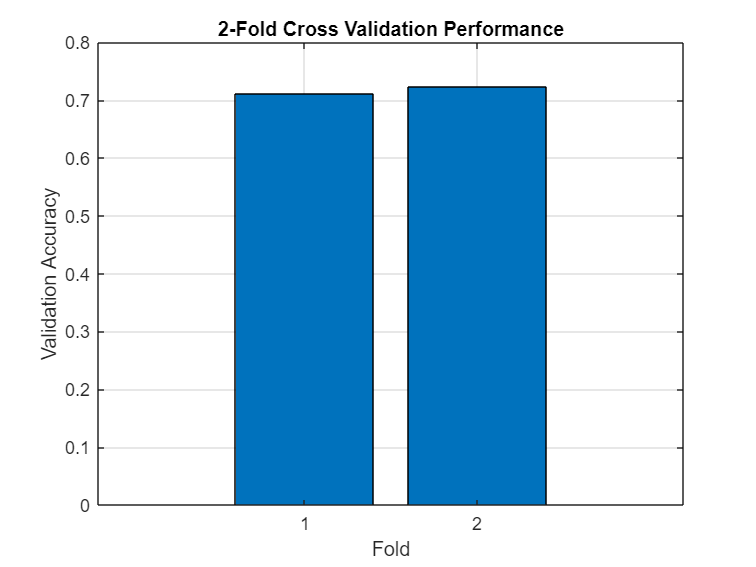

% Plot the validation on a graph
% NOTE, the 2 folds is not preferable, but it took nearly 2 hours to run as
% is with 2 folds, so I will need to work on that.
KfoldTest = figure;
bar(1:K, accuarcies);
xlabel('Fold');
ylabel('Validation Accuracy');
title('2-Fold Cross Validation Performance');
grid on;
filename = sprintf('cnnAccuracy.png');
outputFile = fullfile("figures/",filename);
exportgraphics(KfoldTest,outputFile,'Resolution',1200);